Kandidaatintyö 2022

Markus Hautala

Matlab SLAMien vertailu käyttäen lidar-anturia ROSin kautta

-------------------------------------------------------------

Tämä skripti sisältää kandidaatintyöhön sisältyvän testauksen. Osiot etenevät siinä järjestyksessä, miten testit ovat edenneet.

Tiedoston voi ajaa kerralla, mutta se vaatii suuren määrän keskusmuistia.

Työtilan valmistelu

 
% Poista kaikki entiset muuttujat, ikkunat ja komentohistoria
clc
clear all
close all

% Lisää alihakemistot
mainfolder = getPath;
addpath(genpath(strcat(mainfolder,'\Algorithms')));
addpath(genpath(strcat(mainfolder,'\Tools')));
addpath(genpath(strcat(mainfolder,'\ignore')));

Tallenna data käyttäen joko ROSista lukua tai tallennettua dataa matlab-muodossa.

Tallennetun datan paketin latausosoite on alla. Tämä sisältää tiedoston "savedData_final.mat", joka sisältää testaukseen perustuvan matlab-tietotyypin datan.

Hakemistossa on myös tiedosto "originalRosData.bag", joka sisältää alkuperäisen rosbag-tallenteen testauksesta.

[https://tuni-my.sharepoint.com/:f:/g/personal/markus_hautala_tuni_fi/EqMrzbfX0W1BkObC2WGypbwBZJshim-_KwTy8prTLD4_nw?e=M3OFuB](https://tuni-my.sharepoint.com/:f:/g/personal/markus_hautala_tuni_fi/EqMrzbfX0W1BkObC2WGypbwBZJshim-_KwTy8prTLD4_nw?e=M3OFuB)

 
choose = "saved"

choose = "saved"


if choose == "sensor"
    % tallenna anturista
    time = 60;
    topic = "velodyne_points";
    IP_address = "127.0.0.1";
    pcSet = saveRosData(time, topic, IP_address);

elseif choose == "saved"
    % Vaihtoehtoisesti käytetään tallennettua dataa.
    load("savedData_final.mat")
end

Esikäsittelytestaus yksittäiselle pistepilvelle. (Luku 4)

Datapaketti sisältää yksittäisen pistepilven "pc", jolla testataan eri esikäsittelymenetelmiä pistepilvikuvien avulla.

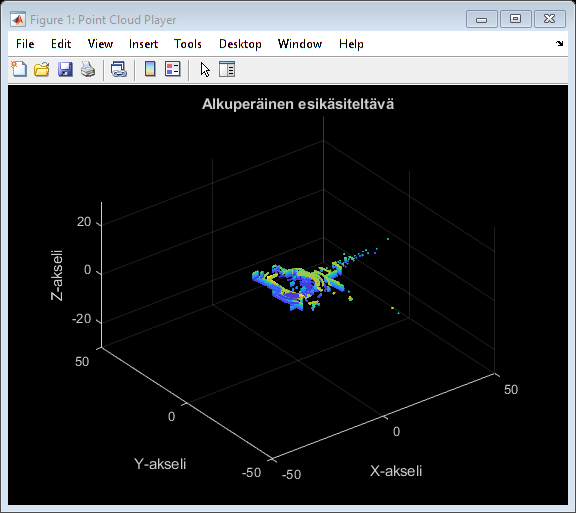

 
show1 = showPc('Alkuperäinen esikäsiteltävä', pc);

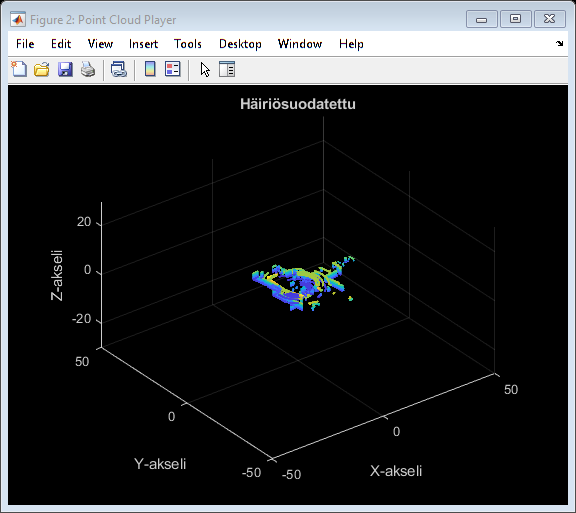


%% Häiriösuodatus (luku 4.4)
pc_denoised = pcdenoise(pc);
show2 = showPc('Häiriösuodatettu', pc_denoised);


% Kuinka paljon pisteitä hävisi:
losed_points = size_of_pc(pc) - size_of_pc(pc_denoised)

losed_points = 35



%% Alinäytteistys (luku 4.5)
laatikon_koko = 0.1; % (m)
tic
pc_downsampled_grid = pcdownsample(pc, 'gridAverage', laatikon_koko);
time_of_grid = toc

time_of_grid = 0.1055

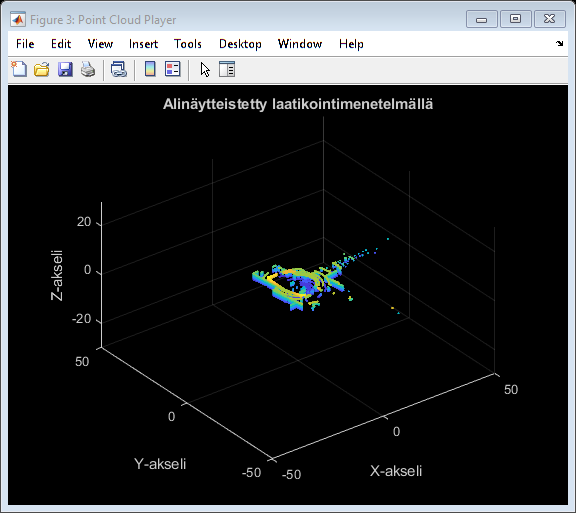

show3 = showPc('Alinäytteistetty laatikointimenetelmällä', pc_downsampled_grid);


% Prosentuaalinen pistepilven koko verrattuna ennen alinäytteistystä:
pros_koko = size_of_pc(pc_downsampled_grid) / size_of_pc(pc)

pros_koko = 0.3844


% Verrataan satunnaismenetelmään:
tic
pc_downsampled_rand = pcdownsample(pc, "random", pros_koko);
time_of_random = toc

time_of_random = 0.0600

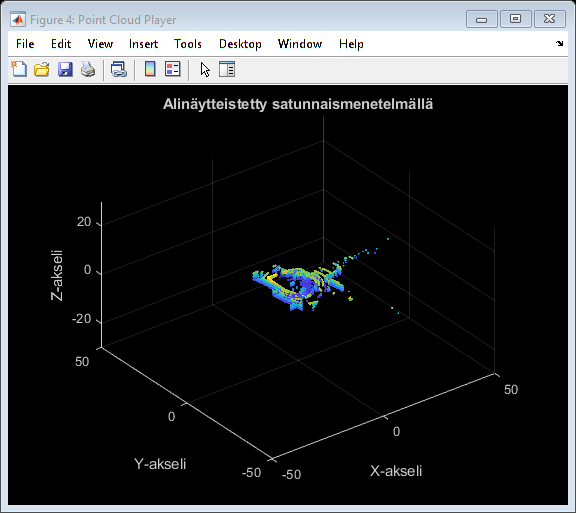

show4 = showPc('Alinäytteistetty satunnaismenetelmällä', pc_downsampled_rand);

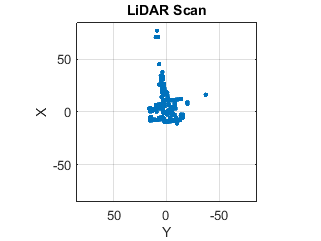



% 3D to 2D (luku 4.7)
lidarScan_limited = pc2laser({pc}, -0.5, 1.5);
figure
plot(lidarScan_limited{1});

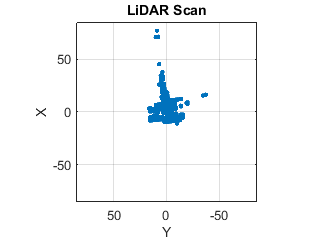


lidarScan_unlimited = pc2laser({pc}, -50, 50);
figure
plot(lidarScan_unlimited{1});

Esikäsittely SLAM-algoritmeille. (Luku 4.10 Valittava data SLAM-algoritmille)

 
eachFrame = 2;
preprocessedpcSet = preprocess(pcSet, eachFrame);
lidarSet = pc2laser(preprocessedpcSet, -0.5, 1.5);
size_of_psSet(preprocessedpcSet)

ans = 323

Reaalikartta lattian teippimerkinnöistä

figure
x = groundTruth(:,1);
y = groundTruth(:,2);
plot(x, y)
for t = 1:9
  text(x(t)+0.1,y(t)+0.1,[num2str(t), ':  (', num2str(x(t)), ',', num2str(y(t)), ')'])
end

SLAM-esimerkkiskriptien suoritus

 
disp('Navigation Toolbox')
tic
optimizedPoses = navigationTB_example(lidarSet)
navigationTB_time = toc;
[routelengths_navi, distances_navi] = getResults(optimizedPoses, groundTruth, eachFrame);

 
disp('Computer vision toolbox')
tic
computerVisionTB_example1
computerVisionTB1_time = toc;
[routelengths_vision, distances_vision] = getResults(pcViewSet2vect(vSet), groundTruth, eachFrame);

 
disp('Lidar toolbox')
tic
lidarTB_example
lidarTB_time = toc;
[routelengths_lidar, distances_lidar] = getResults(updatedPGraph.nodeEstimates, groundTruth, eachFrame);

Lasketaan tulokset

calculateResults

4.16 Pistepilvien jatkokäsittely

Esikäsittelytestausten testaus parhaimmalla SLAM-skriptillä = navigationTB_example

Pisteiden määrä pistepilvissä (kuvaaja)

[points_in_pc_mean, lengths_original_pcSet] = mean_points_in_pc(pcSet);
plot(lengths_original_pcSet)

Alinäytteistys vs näytteenottotaajuus (Luku 4.16.1)

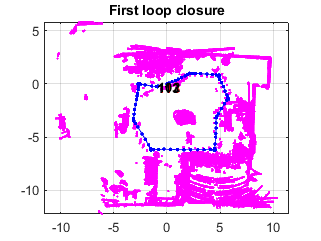

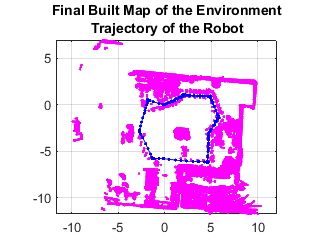

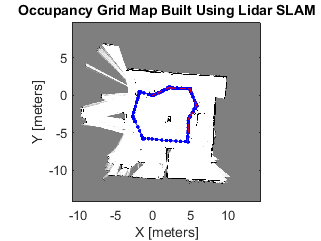

downsampleVSsamplerate1 =   SLAMprocess with properties:

                  eachFrame: 4
           performPcDenoise: 0
           downsamplemethod: 'random'
    downsampleToPointAmount: 8000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×162 cell}
                   lidarSet: {1×162 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [162×3 double]
            time_preprocess: [2×1 double]
                  time_SLAM: 810.5355
               results_time: [3×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]


downsampleVSsamplerate1 = SLAMprocess(pcSet, groundTruth);
downsampleVSsamplerate1.eachFrame = 4*1;
downsampleVSsamplerate1.performPcDenoise = false;
downsampleVSsamplerate1.downsamplemethod = 'random';
downsampleVSsamplerate1.downsampleToPointAmount = 4*2000;
downsampleVSsamplerate1 = downsampleVSsamplerate1.runAll

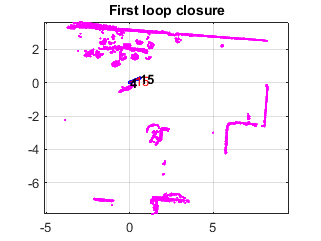

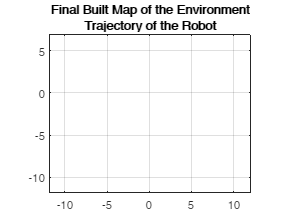

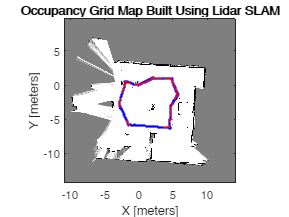

downsampleVSsamplerate2 =   SLAMprocess with properties:

                  eachFrame: 1
           performPcDenoise: 0
           downsamplemethod: 'random'
    downsampleToPointAmount: 2000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×646 cell}
                   lidarSet: {1×646 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [646×3 double]
            time_preprocess: [2×1 double]
                  time_SLAM: 984.4914
               results_time: [3×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]



downsampleVSsamplerate2 = SLAMprocess(pcSet, groundTruth);
downsampleVSsamplerate2.eachFrame = 1*1;
downsampleVSsamplerate2.performPcDenoise = false;
downsampleVSsamplerate2.downsamplemethod = 'random';
downsampleVSsamplerate2.downsampleToPointAmount = 1*2000;
downsampleVSsamplerate2 = downsampleVSsamplerate2.runAll


downsampleVSsamplerate_results_map = [downsampleVSsamplerate1.results_map downsampleVSsamplerate2.results_map];
downsampleVSsamplerate_results_mtime = [downsampleVSsamplerate1.results_time downsampleVSsamplerate2.results_time];

Häiriösuodatuksen vaikutus (Luku 4.16.2)

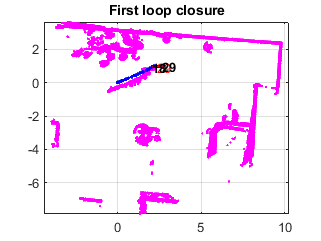

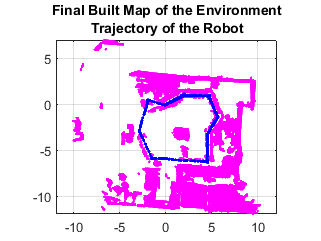

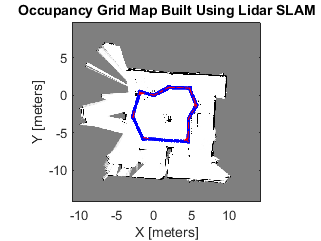

pcdenoise_results1 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 1
           downsamplemethod: 'random'
    downsampleToPointAmount: 10000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: [2×1 double]
                  time_SLAM: 1.7862e+03
               results_time: [3×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]


pcdenoise_results1 = SLAMprocess(pcSet, groundTruth);
pcdenoise_results1.eachFrame = 2;
pcdenoise_results1.performPcDenoise = true;
pcdenoise_results1.downsamplemethod = 'random';
pcdenoise_results1.downsampleToPointAmount = 10000;
pcdenoise_results1 = pcdenoise_results1.runAll

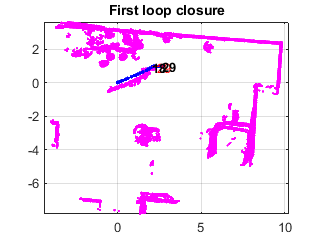

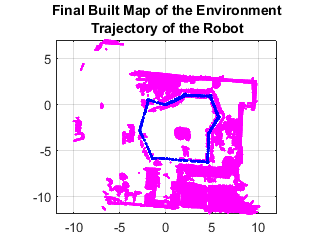

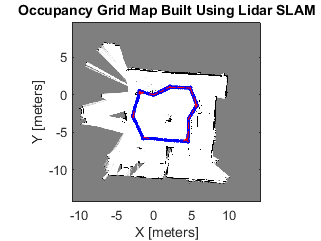

pcdenoise_results2 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 0
           downsamplemethod: 'random'
    downsampleToPointAmount: 10000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: [2×1 double]
                  time_SLAM: 1.7732e+03
               results_time: [3×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]



pcdenoise_results2 = SLAMprocess(pcSet, groundTruth);
pcdenoise_results2.eachFrame = 2;
pcdenoise_results2.performPcDenoise = false;
pcdenoise_results2.downsamplemethod = 'random';
pcdenoise_results2.downsampleToPointAmount = 10000;
pcdenoise_results2 = pcdenoise_results2.runAll


pcdenoise_results_map = [pcdenoise_results1.results_map pcdenoise_results2.results_map];
pcdenoise_results_mtime = [pcdenoise_results1.results_time pcdenoise_results2.results_time];

Alinäytteistysmenetelmät (Luku 4.16.3)

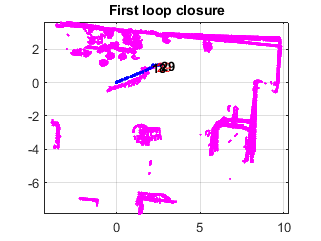

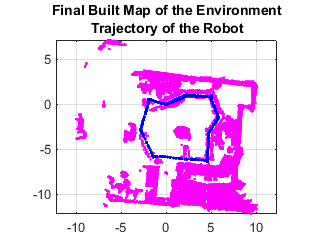

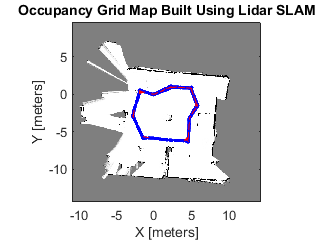

gridvsrandom_results1 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 1
           downsamplemethod: 'gridAverage'
    downsampleToPointAmount: 0.1000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: [2×1 double]
                  time_SLAM: 637.2649
               results_time: [3×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]


gridvsrandom_results1 = SLAMprocess(pcSet, groundTruth);
gridvsrandom_results1.eachFrame = 2;
gridvsrandom_results1.downsamplemethod = 'gridAverage';
gridvsrandom_results1.downsampleToPointAmount = 0.1;
gridvsrandom_results1 = gridvsrandom_results1.runAll

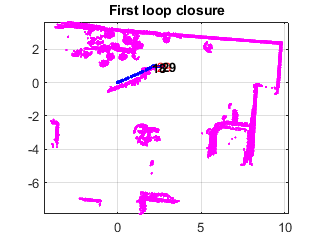

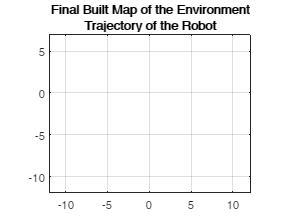

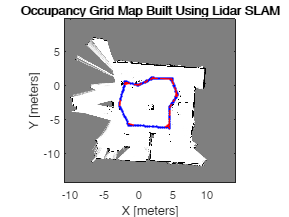

gridvsrandom_results2 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 1
           downsamplemethod: 'random'
    downsampleToPointAmount: 6.5516e+03
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: [2×1 double]
                  time_SLAM: 1.1625e+03
               results_time: [3×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]



gridvsrandom_results2 = SLAMprocess(pcSet, groundTruth);
gridvsrandom_results2.eachFrame = 2;
gridvsrandom_results2.downsamplemethod = 'random';
gridvsrandom_results2.downsampleToPointAmount = mean_points_in_pc(gridvsrandom_results1.pcSet_preprocessed);
gridvsrandom_results2 = gridvsrandom_results2.runAll


gridvsrandom_results_map = [gridvsrandom_results1.results_map gridvsrandom_results2.results_map];
gridvsrandom_results_mtime = [gridvsrandom_results1.results_time gridvsrandom_results2.results_time];

SLAMien vertailu laskennallisesti parhaalla esikäsittelymenetelmäkombinaatiolla (luku 4.17)

eachFrame_2nd_iteration = 2;
preprocessedpcSet = preprocess_tested(pcSet, eachFrame_2nd_iteration);
lidarSet = pc2laser(preprocessedpcSet, -0.5, 1.5);

 
disp('Navigation Toolbox')

Navigation Toolbox


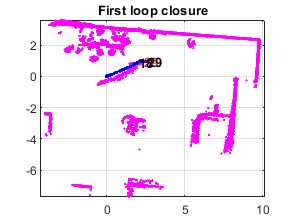

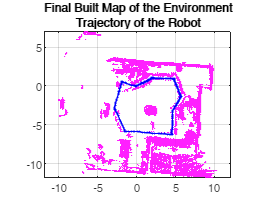

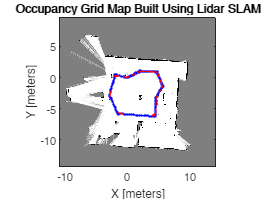

optimizedPoses =          0         0         0
   -0.0092    0.0149    0.2143
    0.0238    0.0306    0.2100
    0.0838    0.0369    0.2090
    0.1726    0.0844    0.2314
    0.2831    0.1392    0.2341
    0.4748    0.2105    0.2395
    0.6171    0.2692    0.2514
    0.8340    0.3491    0.2787
    0.9781    0.4210    0.2890


tic
optimizedPoses = navigationTB_example(lidarSet)

navigationTB_time2 = toc;
[routelengths_navi2, distances_navi2] = getResults(optimizedPoses, groundTruth, eachFrame_2th);

 
disp('Computer vision toolbox')

Computer vision toolbox


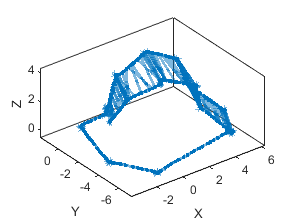

tic
computerVisionTB_example_2nd_iteration

computerVisionTB1_time2 = toc;
[routelengths_vision2, distances_vision2] = getResults(pcViewSet2vect(vSet), groundTruth, eachFrame_2th);

 
disp('Lidar toolbox')

Lidar toolbox


scans = 1×323 cell array
    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1

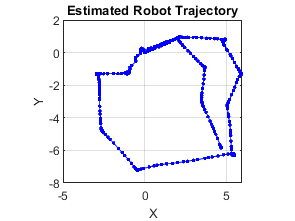

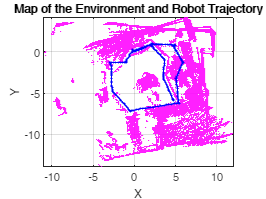

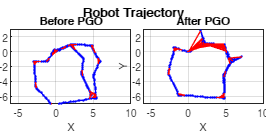

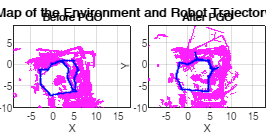

tic
lidarTB_example

lidarTB_time2 = toc;
[routelengths_lidar2, distances_lidar2] = getResults(updatedPGraph.nodeEstimates, groundTruth, eachFrame_2th);

Results:

calculateResults_2nd

routelengths_keskiarvo = 1×3 single row vector
    0.2034   -0.0419    0.5908


distances_keskiarvo = 1×3 single row vector
    0.3604    1.1665    0.4538


final_tulos = 1×3 single row vector
   28.8249   -1.3619   61.2499
